num=1;
den=[1 10 20];
g=tf(num,den)


g =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.



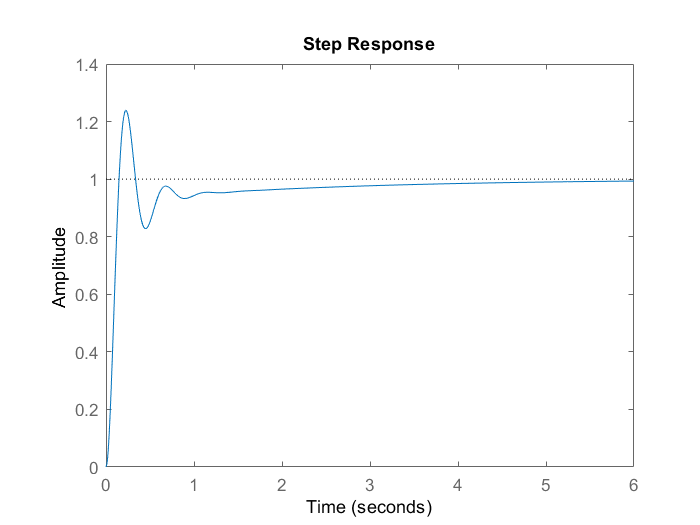

t=feedback(g,1);

kp=200;
ki=90;
kd=0;
cont=pid(kp,ki);
step(feedback(cont*t,1));

stepinfo(feedback(cont*t,1))

ans = struct with fields:
        RiseTime: 0.1000
    SettlingTime: 3.3383
     SettlingMin: 0.8279
     SettlingMax: 1.2388
       Overshoot: 23.8845
      Undershoot: 0
            Peak: 1.2388
        PeakTime: 0.2306


k=dcgain(cont*t);
1/(1+k)

ans = 0